# **PRACTICE 4 - SUPPORT VECTOR MACHINE**

**Andrés Herencia and Antonio Fernández**

**MUTECI 2023-2024**

## Exercise 1

From the data given in the file `svm_nolineal.txt`, the following is requested:

- a) Apply the SVM model to separate lineally data into two categories.

- b) Apply the soft model with different values of the parameter `C > 0` to solve the classification problem.

- c) Use a polynomial kernel to solve the binary classification problem. If this is not possible, use the soft approach with the polynomial kernel by varying the parameter `C`.

***NOTE****: use quadratic programming software and, if applicable, the appropriate kernel function.*

Firstly, we will represent our data.

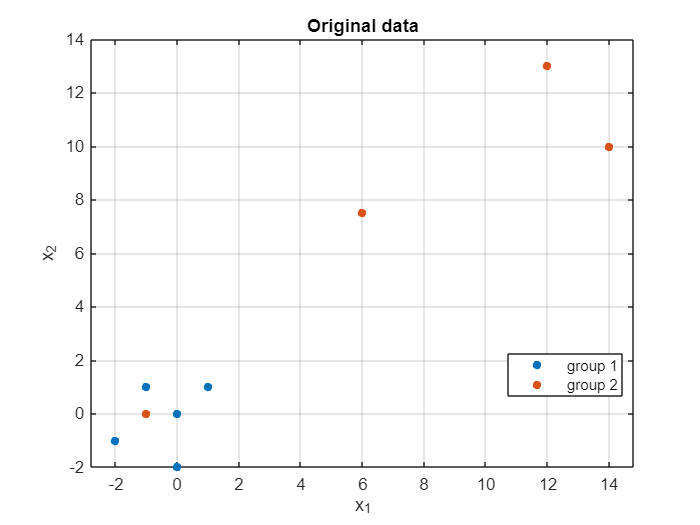

clc, clear, clf
cd 'C:\Users\andre\Documents\UNIVERSIDAD\MUTECI\BLOQUE 2\TOPT\lab\P4'
% cd 'C:\Users\anton\OneDrive\TOPT\Práctica 4'

data = importdata('svm_nolineal.txt', '\t');
X1 = data.data(:, 1); X2 = data.data(:, 2); Y = data.data(:,3);

figure(1)
gscatter(X1, X2, Y)
xlabel("x_1")
ylabel("x_2")
grid on
legend('group 1', 'group 2')
title('Original data')

### a) Apply the SVM model to separate lineally data into two categories.

The primal support vector machine problem will be:


$$P :
  \begin{cases}
   \displaystyle \min_{\mathbf{w},b} \; & \frac{1}{2} \| \mathbf{w} \|^2\\
    \text{such to } \; & -y^i(\mathbf{w}^t\mathbf{x}^i - b) \le -1, \quad \forall i \in \{1,2,\dots, m\}
  \end{cases}$$


svm=fitcsvm([X1,X2],Y);
svm.Beta

ans =     0.0003
    0.3075


b = svm.Bias

b = -1.3076

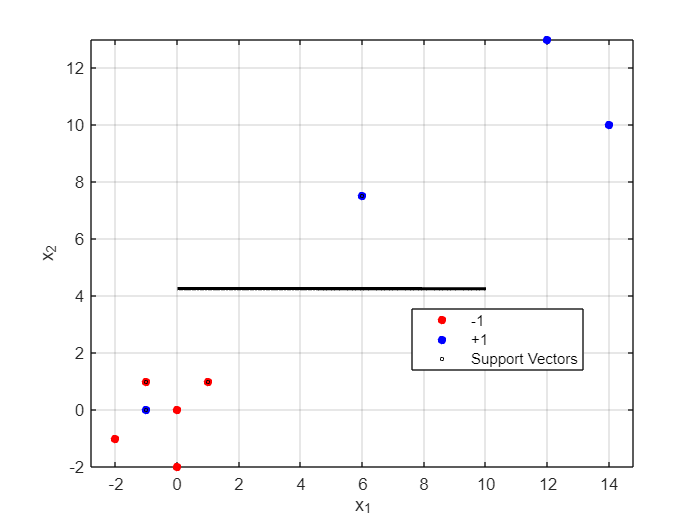

d = 0.02;
[x1Grid,x2Grid] = meshgrid(0:d:10,0:d:10);
    
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(svm,xGrid);

figure;
h(1:2) = gscatter(X1,X2,Y,'rb','.');
hold on
X=[X1,X2];
h(3) = plot(X(svm.IsSupportVector,1),X(svm.IsSupportVector,2),'ko', 'MarkerSize',2);
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k', 'LineWidth',2);
legend(h,{'-1','+1','Support Vectors'});
grid on
xlabel("x_1")
ylabel("x_2")
hold off

How could we predict just by looking at the data, we cannot separate the two categories linearly. We will see that the quadratic problem is not feasible.

n = 2;
m = size(X1, 1);
H=zeros(n+1);
%indpos=Y>0;
%indneg=Y<0;
H(1:n,1:n)= eye(n);
f=zeros(n+1,1);
A=zeros(m,n+1);
A(:,1)=-1*Y.* X1;
A(:,2)=-1*Y.* X2;
A(:,3)=Y;
b= -1*ones(m,1);

quadprog(H,f,A,b,[],[],[],[]);


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>


### b) Apply the soft model with different values of the parameter `C > 0` to solve the classification problem.

***NOTE:**** In this section, we will make use of a pre-built function, *`fitcsvm`*. The soft model primal-dual problem is solved using quadratic programming in **Exercise 2**.*

The soft model has the following form:


$$P :
  \begin{cases}
   \displaystyle \min_{\mathbf{w},b} \; & \frac{1}{2} \| \mathbf{w} \|^2 + C\left(\textstyle \sum_{i=1}^{m} \xi_i\right)\\
    \text{such to } \; & y^i(\mathbf{w}^t\mathbf{x}^i - b) \ge 1 - \xi_i, \quad & \forall i \in \{1,2,\dots, m\} \\
& \xi_i \ge 0, \quad & \forall i\in\{1,2,\dots,m\}
  \end{cases}$$


The dual problem is:


$$D_C :
  \begin{cases}
   \displaystyle \min_{a\in\Re^m} \; & \Bigl\{ \frac{1}{2}\sum_{j=1}^{m}\sum_{i=1}^{m}\alpha_i\alpha_iy^iy^j(\mathbf{x}^j)^t\mathbf{x}^i - \textstyle \sum_{i=1}^{m}\alpha_i\Bigl\} \\ 
    \text{such to } & \textstyle \sum_{i=1}^{m} \alpha_i y^i = 0 \quad  \forall i\in\{1,2,\dots,m\}\\
& 0 \le \alpha_i \le C, \quad  \forall i\in\{1,2,\dots,m\}
  \end{cases}$$


We will try different $C$ values :` [0.01, 1]`. We built a function that plot the decission boundary, which can be found on annexes. 

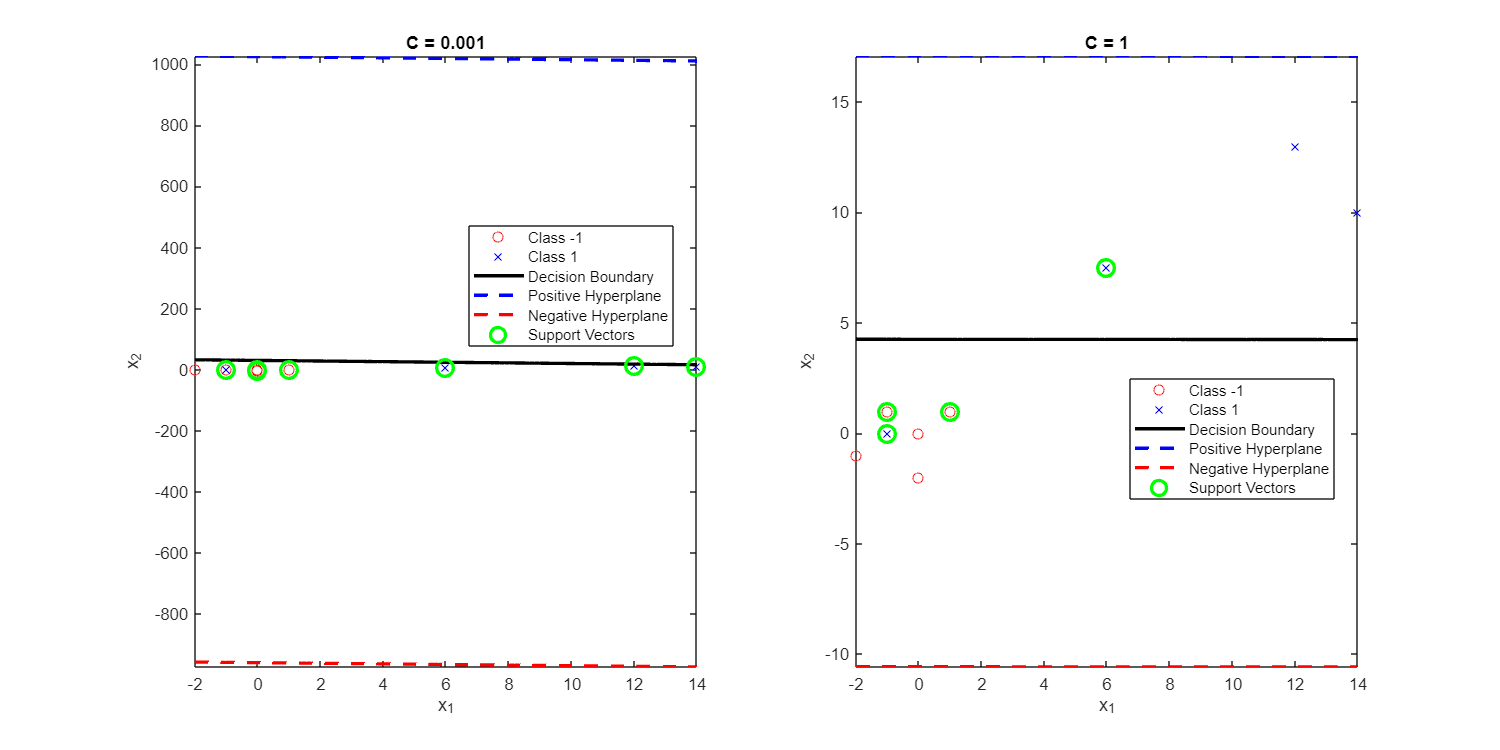

C_values = [0.001, 1]; % Adjust this list as needed

% Initialize a cell array to store the SVM models
models = cell(length(C_values), 1);

% Train SVM models with different values of C
for i = 1:length(C_values)
    C = C_values(i);
    SVMModel = fitcsvm(X, Y, 'KernelFunction', 'linear', 'BoxConstraint', C);
    models{i} = SVMModel;
end


cols = 2;
rows = round(length(C_values)/cols);

% Plot the data and decision boundaries for each model
figure('Position', [100, 100, 1200, 600]);

for i = 1:length(C_values)
    subplot(rows, cols, i); % Adjust subplot parameters based on the number of C values
    SVMModel = models{i};
    h = plotDecisionBoundary(X, Y, SVMModel);
    title(['C = ' num2str(C_values(i))]);
    legend('Location', 'Best');
end

We can observe how the separation line changes its slope. For $C$ values greater than 1, there are no differences in position or slope. Additionally, it can be observed that from $C=0.001$ onwards, the accuracy does not improve.

### c) Use a polynomial kernel to solve the binary classification problem. If this is not possible, use the soft approach with the polynomial kernel by varying the parameter `C`.

Firstly, we will try to solve the problem with $C=\infty$.

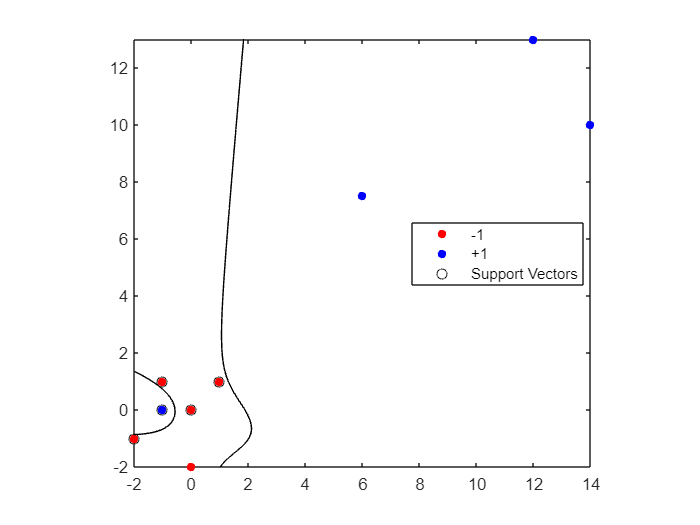

svm=fitcsvm(X,Y,'KernelFunction','polynomial');

sv = svm.SupportVectors; 
var_dual = zeros(m,1);
var_dual(svm.IsSupportVector)=svm.Alpha;

[x1Grid,x2Grid] = meshgrid(linspace(min(X(:, 1)), max(X(:, 1)), 1000), ...
                          linspace(min(X(:, 2)), max(X(:, 2)), 1000));
    
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(svm,xGrid);

figure;
h(1:2) = gscatter(X(:,1),X(:,2),Y,'rb','.');
hold on

h(3) = plot(X(svm.IsSupportVector,1),X(svm.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

It can be observed that the polynomial kernel perfectly solves the problem, and therefore, a relaxed approach is not necessary. Anyway, let's see that with $C=1$, the result doesn't change.

svm = fitcsvm(X,Y,'KernelFunction','polynomial','BoxConstraint', 1);
    
[~,scores] = predict(svm,xGrid);

figure;
h(1:2) = gscatter(X(:,1),X(:,2),Y,'rb','.');
hold on

h(3) = plot(X(svm.IsSupportVector,1),X(svm.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

## Exercise 2

From the data given in the file square4.txt or square4.xlsx, the following is requested:

- a) Apply a Support Vector Machine for separating lineally the groups 0 and 2.

- b) Apply the soft model with different values for the parameter `C>0` to solve the classification problem.

- c) Determine which value of `C` is the most suited for this problem. Justify the answer.

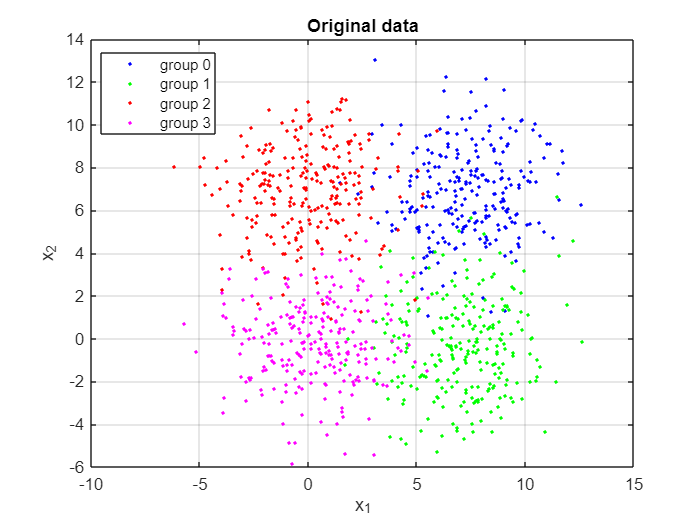

clear; clc; clf

data = readmatrix('square4.txt');
X1 = data(:, 1); X2 = data(:, 2); Y = data(:, 3);

figure(1)
gscatter(X1, X2, Y, 'bgrm')
grid on
xlabel("x_1")
ylabel("x_2")
legend('group 0', 'group 1','group 2', 'group 3')
title('Original data')

### a) Apply a Support Vector Machine for separating lineally the groups 0 and 2.

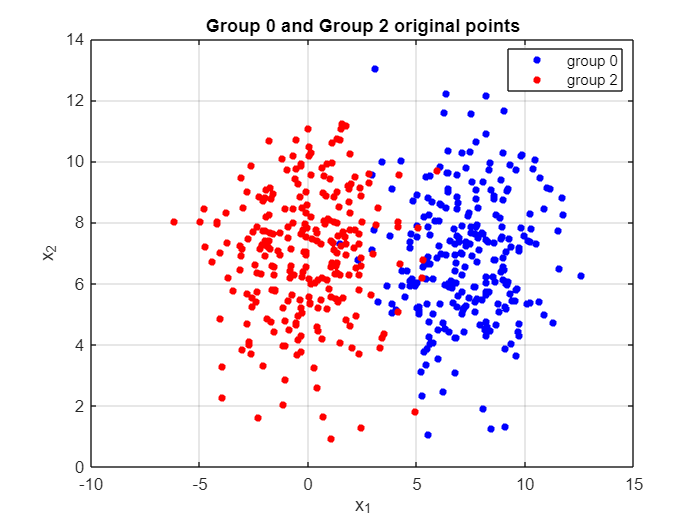

ind1 = Y==0; 
ind2 = Y==2;
x1 = X1(ind1 | ind2);
x2 = X2(ind1 | ind2);
y = Y(ind1 | ind2);
y(y==0) = -1; y(y==2) = +1;
figure(2)
gscatter(x1, x2, y, 'br')
grid on
xlabel("x_1")
ylabel("x_2")
legend('group 0', 'group 2')
title('Group 0 and Group 2 original points')

We can observe graphically that there is **no linear separator for this data groups**. If we try to optimize the primal problem for the SVM...

% 1. Quadratic term of the objective function
n = 2; % number of groups
m = size(x1,1); % size of each group
H = zeros(n+1); % hessian
H(1:n,1:n) = eye(n)

H =      1     0     0
     0     1     0
     0     0     0


% 2. Linear term of the objective function (0)
f = zeros(n+1,1);
% 3. A matrix with linear conditions
A = zeros(m,n+1);
A(:,1) = -1*y.* x1; 
A(:,2) = -1*y.* x2; 
A(:,3) = y;
A

A =     6.2853   11.5879   -1.0000
    9.3978    5.4489   -1.0000
    5.7362    8.6803   -1.0000
    6.1020    9.8327   -1.0000
    9.2948    5.6737   -1.0000
    8.0270    7.6795   -1.0000
    5.0270    6.0370   -1.0000
    3.0486    7.7805   -1.0000
    2.9635    9.5684   -1.0000
    6.8647    8.8412   -1.0000


% b term
b = -1*ones(m,1);
[wb,ff,exitflag] = quadprog(H,f,A,b,[],[],[],[])


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>


wb =    -0.2891
    0.0096
   -0.9591


ff = 0.0418

exitflag = -2

We can see that, indeed, there is no feasible solution to this problem.

A lot of points have been misclassified. Then, we need to "relax" this model for penalizing those points that would have been misclassified using a soft model. 

### b) Apply the soft model with different values for the parameter `C>0` to solve the classification problem.

The soft model has the following form:


$$P :
  \begin{cases}
   \displaystyle \min_{\mathbf{w},b} \; & \frac{1}{2} \| \mathbf{w} \|^2 + C\left(\textstyle \sum_{i=1}^{m} \xi_i\right)\\
    \text{such to } \; & y^i(\mathbf{w}^t\mathbf{x}^i - b) \ge 1 - \xi_i, \quad & \forall i \in \{1,2,\dots, m\} \\
& \xi_i \ge 0, \quad & \forall i\in\{1,2,\dots,m\}
  \end{cases}$$


From the previous model, they have been included $m$ variables $\xi_i \ge 0$ to identify those points $\mathbf{x}^i$ that have been misclassified. These variables act on those points that are on the wrong side of the plane and penalize them based on their value.

On the other hand, the value of $C$ penalizes failure to comply with prior constraints. This is, the higher the value, the greater the penalization. In the limit case, when $C\to \infty$ tends to be infinite, the previous model converges to the first model with the proposed separator hyperplane ($H$), narrowing the band where the hyperplane $H^+$ and $H^-$ are located. Meanwhile, a low value ($C\to0$) will widen the strip, allowing it to contain more points that should be misclassified.

The dual problem is:


$$D_C :
  \begin{cases}
   \displaystyle \min_{a\in\Re^m} \; & \Bigl\{ \frac{1}{2}\sum_{j=1}^{m}\sum_{i=1}^{m}\alpha_i\alpha_iy^iy^j(\mathbf{x}^j)^t\mathbf{x}^i - \textstyle \sum_{i=1}^{m}\alpha_i\Bigl\} \\ 
    \text{such to } & \textstyle \sum_{i=1}^{m} \alpha_i y^i = 0 \quad  \forall i\in\{1,2,\dots,m\}\\
& 0 \le \alpha_i \le C, \quad  \forall i\in\{1,2,\dots,m\}
  \end{cases}$$


We can determine the vector $\mathbf{\bar w}$ in the same way as the strict model does, as a function of $ \bar \alpha$: $\mathbf{\bar w} = \sum_{i=1}^m \bar{\alpha_i} y^i \mathbf{x}^i$.

Thus, to solve this problem we have to:

- 1.- Characterize the quadratic term of the objective function.

- 2.- Compute the linear term of the objective function.

- 3.- Obtain the equation matrix and the independent term of the objective function.

- 4.- Apply the model with some values of $C$ and represent graphically their hyperplane bounds. We will take the following values of C in a logarithmic scale, between `1e-4` and `1e+4.`

- 5.- Compare the models (in section c).

% 1.
H=(([x1,x2]).*y)*([x1,x2].*y)'

H =   173.7845  122.2091  136.6408  152.2927  124.1673  139.4411  101.5518  109.3217  129.5043  145.5974  157.7962   93.9872  114.5039  137.9891  117.5149  158.3637  117.1311  143.4792  102.8121  108.3664  110.6915   92.1133  159.3635  182.2620   60.2119  115.6694  123.8295   96.6178  144.7858  119.7137  108.9778  117.3941  175.5962  132.7111  144.5838  132.7649  138.3224  165.2499   83.2250  125.7261   89.6637   91.8553  131.5489  162.1242  131.4256   93.3501   91.3886  136.3067   84.6107  113.8252
  122.2091  118.0082  101.2060  110.9220  118.2657  117.2806   80.1371   71.0455   79.9874  112.6873  132.1376   84.3864  110.6684  104.0266  101.0641  128.9394  108.0038  124.9511   94.0900   95.5426   99.7840   85.2082  121.9488  152.9783   62.1041  117.0141  111.2479   91.7710  109.5993   95.8587   92.0616  113.8740  158.0378  117.7996  130.7156  105.7924  105.9462  131.5513   76.1692  131.7686   80.7407   66.6422  119.9602  150.5331   93.0251   58.9598   76.0032  112.6638   75.6966  105

% 2. 
f=-1*ones(m,1)

f =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


% 3.
Aeq = zeros(1,m);
Aeq(1,:) = y'

Aeq =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


beq = 0

beq = 0

#### Parameter C = 10^-4


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


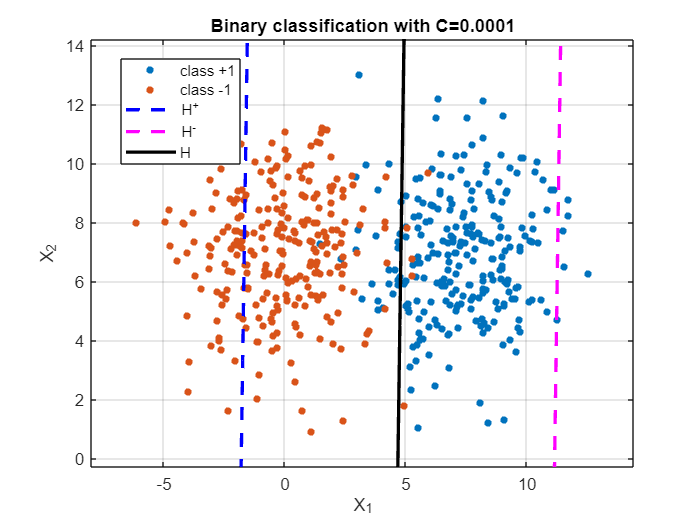

pr0 = 0.9420

ph0 = 0.1360

C0 = 1e-4;
[pr0, ph0] = svm_soft(x1,x2,y,H,f,Aeq,beq,C0,true)

#### Parameter C = 10^-3

C1 = 0.001

C1 = 1.0000e-03


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


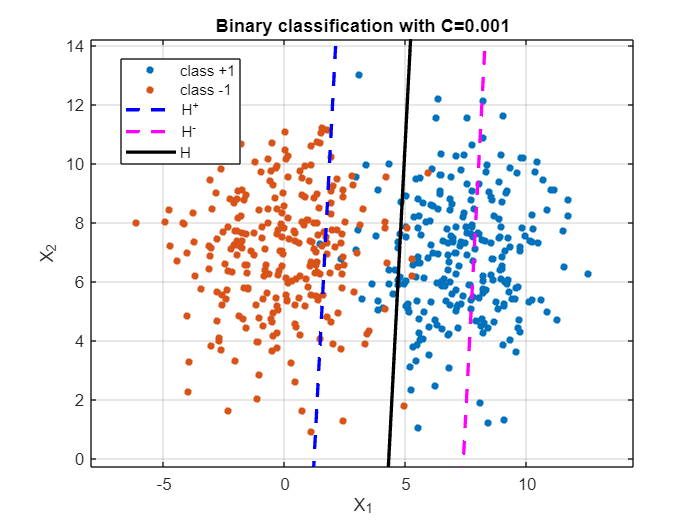

pr1 = 0.9440

ph1 = 0.6040

[pr1, ph1] = svm_soft(x1,x2,y,H,f,Aeq,beq,C1,true)

#### Parameter C = 0.01


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


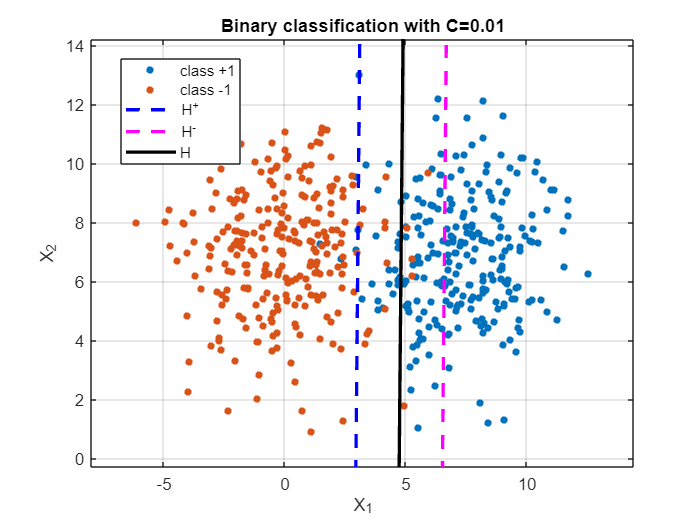

pr2 = 0.9400

ph2 = 0.7980

C2 = 1e-2;
[pr2, ph2] = svm_soft(x1,x2,y,H,f,Aeq,beq,C2,true)

#### Parameter C = 0.1


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


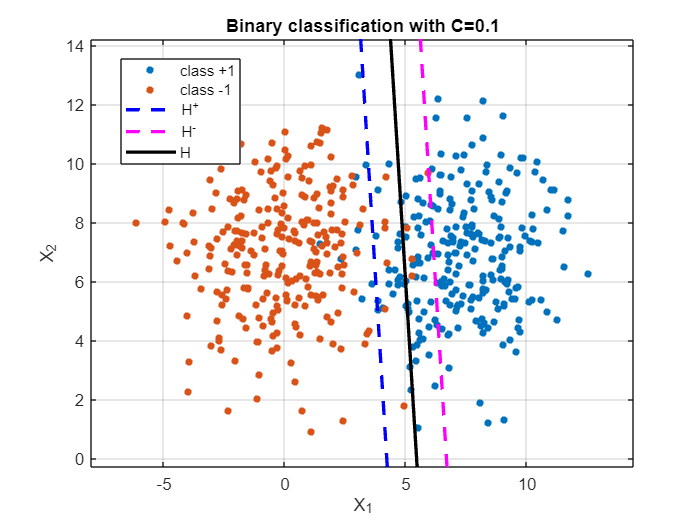

pr3 = 0.9340

ph3 = 0.8560

C3 = 1e-1;
[pr3, ph3] = svm_soft(x1,x2,y,H,f,Aeq,beq,C3,true)

#### Parameter C = 1


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


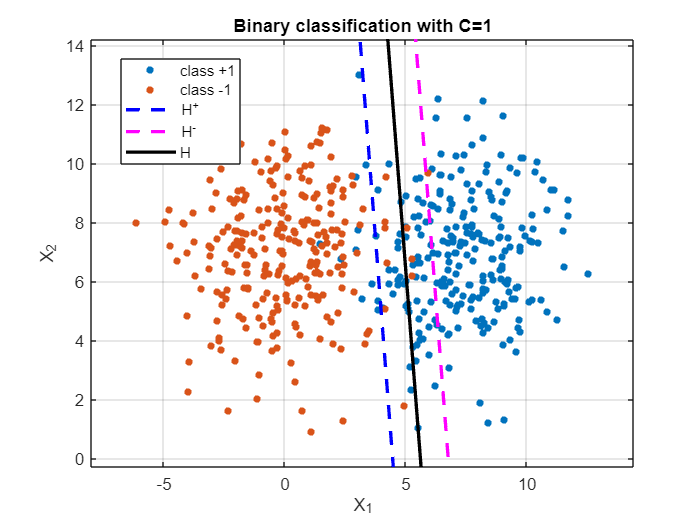

pr4 = 0.9300

ph4 = 0.8640

C4 = 1;
[pr4, ph4] = svm_soft(x1,x2,y,H,f,Aeq,beq,C4,true)

From now on forward, the quadratic optimization problem associated with computing the optimum hyperplane distance returns the same result. Then, we will not show those plots.

#### Parameter C = 10

C5 = 1e1;
[pr5, ph5] = svm_soft(x1,x2,y,H,f,Aeq,beq,C5,false);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### Parameter C = 100

C6 = 1e2;
[pr6, ph6] = svm_soft(x1,x2,y,H,f,Aeq,beq,C6,false);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### Parameter C = 1000

C7 = 1e3;
[pr7, ph7] = svm_soft(x1,x2,y,H,f,Aeq,beq,C7,false);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### Parameter C = 10^4


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


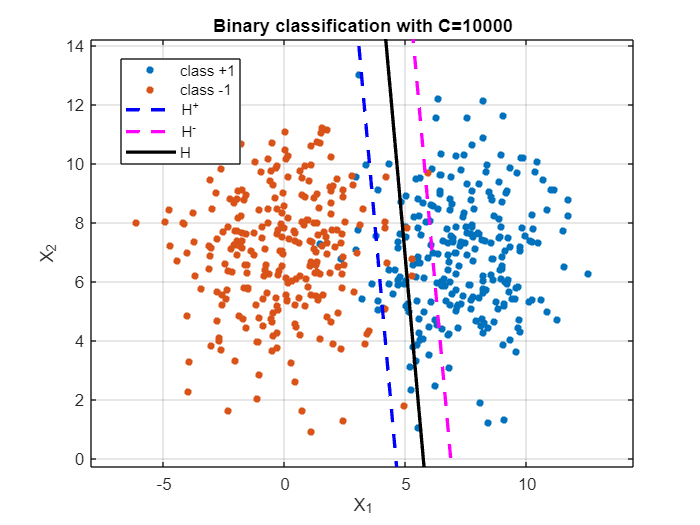

C8 = 1e4;
[pr8, ph8] = svm_soft(x1,x2,y,H,f,Aeq,beq,C8,true);

### c) Determine which value of C is the most suited for this problem. Justify the answer.

Now we must determine which value of $C$ is the most suited for this binary classification. 

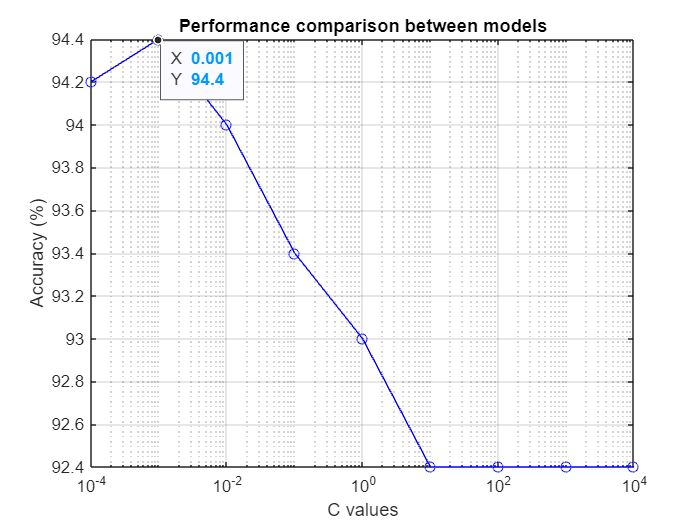

% Definir tus datos
pr = [pr0, pr1, pr2, pr3, pr4, pr5, pr6, pr7, pr8].*100;
C = [C0, C1, C2, C3, C4, C5, C6, C7, C8];

figure;
semilogx(C, pr, 'bo-');
ylabel('Accuracy (%)');
xlabel('C values');

grid on;
title('Performance comparison between models');

ax = gca;
chart = ax.Children(1);
datatip(chart,0.001,94.4);

As we can see, the accuracy gets better when $C=10^{-3}$. But in general, a low value of C allows us to get better results, because both groups are too mixed between them, and a wider margin penalizes less those points.

## Annexes

### Exercise 1

#### Plot decision boundary for SVM soft model

This function takes a SVMModel trained with the package `fitcsvm.`

function h = plotDecisionBoundary(X, Y, SVMModel)
%% Description:
%  Plots the decision boundary, positive hyperplane, negative hyperplane, 
%  and support vectors for the given SVM model.
%
%  Inputs:
%  - X: Input data matrix with two features.
%  - Y: Vector of class labels (-1 or 1).
%  - SVMModel: SVM model trained using fitcsvm.
%
%  Outputs:
%  - h: Figure handle.

gscatter(X(:, 1), X(:, 2), Y, 'rb', 'ox');
hold on;

% Extract parameters
k = SVMModel.KernelParameters.Scale;
b = SVMModel.Bias;

% Calculate slope and intercept
slope = -SVMModel.Beta(1) / SVMModel.Beta(2);
intercept = b / SVMModel.Beta(2);

% Plot decision boundary
xline = linspace(min(X(:, 1)), max(X(:, 1)), 100);
yline = slope * xline - intercept;
plot(xline, yline, 'k-', 'LineWidth', 2);

% Plot positive hyperplane
yline_pos = slope * xline - (intercept - 1) / SVMModel.Beta(2);
plot(xline, yline_pos, 'b--', 'LineWidth', 2);

% Plot negative hyperplane
yline_neg = slope * xline + (intercept + 1) / SVMModel.Beta(2);
plot(xline, yline_neg, 'r--', 'LineWidth', 2);

% Highlight support vectors
idx = SVMModel.IsSupportVector;
plot(X(idx, 1), X(idx, 2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
hold off;
xlabel('x_1');
ylabel('x_2');
legend('Class -1', 'Class 1', 'Decision Boundary', ...
    'Positive Hyperplane', 'Negative Hyperplane', 'Support Vectors');
axis tight;
h = gcf;

end

### Exercise 2

#### SVM soft model using quadratic programming.

function [performance_rate, points_bet_hyp] = svm_soft(x1, x2, y, H, f, Aeq, beq, C, plt)
%% Description:
% Own-made MATLAB function implements a Support Vector Machine (SVM) with a 
% soft margin for binary classification.
%
% Inputs:
% - x1: Feature values for the first dimension.
% - x2: Feature values for the second dimension.
% - y: Class labels (+1 or -1).
% - H: Hessian matrix in the quadratic programming problem.
% - f: Linear coefficient vector in the quadratic programming problem.
% - Aeq: Coefficients for linear equality constraints.
% - beq: Values for linear equality constraints.
% - C: Regularization parameter for the soft margin.
% - plt: Boolean indicating whether to plot the decision boundaries and support vectors (true or false).
%
% Outputs:
% - performance_rate: The rate of correctly classified data points.
% - points_bet_hyp: The proportion of data points located between the decision boundaries.

% Lower and upper bound for the alpha value.
m= size(x1,1);
lb = zeros(m,1);
ub = C * ones(m,1);

[alpha, fun, exitflag] = quadprog(H, f, [], [], Aeq, beq, lb, ub);

if exitflag == -2
    return
else
    % normal vector to the hyperplanes
    w = [x1,x2]'*(alpha.*y);

    % identify support vectors for the class +1:
    for i=1:m
        if y(i) > 0
            indk = i;
        else
            indh = i;
        end
    end

    b = ([x1(indk),x2(indk)]*w + [x1(indh),x2(indh)]*w)/2;

    % Plotting
    % indneg = y<0; indpos = y>0;
    % H^+
    xx1 = min(x1):0.1:max(x1);
    xx2p = (b + 1 - w(1) * xx1)./ w(2);
    % H^-
    xx2n = (b - 1 - w(1) * xx1)./ w(2);
    % H
    xx2 = (b - w(1) * xx1)./ w(2);

    if plt == true
        gscatter(x1, x2, y)
        hold on
        plot(xx1,xx2p,'b--',xx1,xx2n,'m--', xx1,xx2,'k-','LineWidth',2);
        title("Binary classification with C="+num2str(C));
        xlabel('X_1');
        ylabel('X_2');
        ylim([min(x2) - abs(max(x2) - min(x2))/10, ...
            max(x2) + abs(max(x2) - min(x2))/10]);
        xlim([min(x1) - abs(max(x1) - min(x1))/10, ...
            max(x1) + abs(max(x1) - min(x1))/10]);
        legend('class +1','class -1','H^+','H^-','H')
        grid on
        hold off
    end

    % parameters of each hyperplane
    Xx1 = [ones(length(xx1),1), xx1'];
    bn = Xx1\xx2n';
    bp = Xx1\xx2p';
    bh = Xx1\xx2';
    hn = @(x1) bn(1) + bn(2).*x1;
    hp = @(x1) bp(1) + bp(2).*x1;
    h = @(x1) bh(1) + bh(2).*x1;

    % points in a wrong class
    missclassified = 0;
    % points between hyperplanes
    points_hyperplane = 0;
    % validation criterion

    % checking if wether the points fits in the hyperplane or are
    % misclassified
    for k = 1:length(x1)
        if bn(2) < 0
            if (x2(k) > hn(x1(k))) || (x2(k) < hp(x1(k)))
                points_hyperplane = points_hyperplane + 1;
            end
            if (x2(k) > h(x1(k))) && (y(k) ~= -1) || (x2(k) < h(x1(k))) && (y(k) ~= 1)
                missclassified = missclassified + 1;
            end
        else
            if (x2(k) < hn(x1(k))) || (x2(k) > hp(x1(k)))
                points_hyperplane = points_hyperplane + 1;
            end
            if (x2(k) < h(x1(k))) && (y(k) ~= -1) || (x2(k) > h(x1(k))) && (y(k) ~= 1)
                missclassified = missclassified + 1;
            end
        end
    end
    performance_rate = (length(x1)-missclassified)/length(x1);
    points_bet_hyp = points_hyperplane/length(x1);
end
end